# Data integration & VRFT

## Setup - Building the signals required to perform VRFT

We have a set of measurements from the real quad-copter. We have the input signal ($d\Omega$), and the output ($q$). To use this data for VRFT we need to step out of the inner loop. 

The basic cascade VRFT theory assumes that we have the following signals: 

- The input signal $u
$,

- The output of the *inner* part of the plant $y_i$

- The output of the *outer* part of the plant $y_o$

We only have the first two. However the *outer* part of the plant is just an integrator. We just need to integrate $y_i$ to obtain $y_o$.

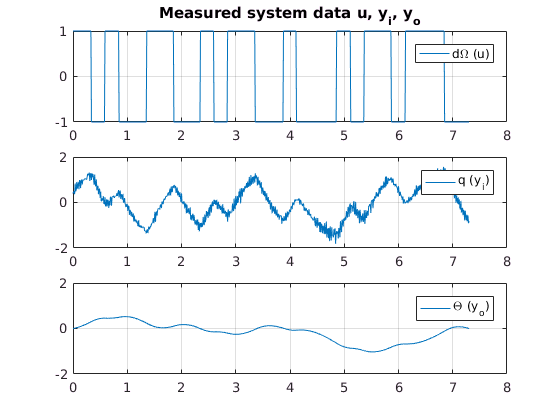

ol_data = load('dati_id_ol.mat');
ol_data.y = ol_data.y * pi / 180;

ol_data.yo = zeros(length(ol_data.y), 1);
ol_data.yo(1) = 0;

for k = 2:length(ol_data.yo)
    time_step = ol_data.t(k) - ol_data.t(k-1);
    ol_data.yo(k) = ol_data.yo(k-1) + ol_data.y(k-1) * time_step;
end

% ol_data.yo = deg2rad(ol_data.yo);

figure();
    subplot 311;    
        plot(ol_data.t, ol_data.u);
        legend('d\Omega (u)');
        title('Measured system data u, y_i, y_o');
    subplot 312;
        plot(ol_data.t, ol_data.y);
        legend('q (y_i)');
        %ylim([-120, 120]);
    subplot 313;
        plot(ol_data.t, ol_data.yo);
        legend('\Theta (y_o)');

The key to cascade VRFT is creating the outer reference from the inner reference


$$r_i(t) = C^{-1}(z) u(t) + y_i(t)  $$


Mixer = 66.667;
Ri = pid(.3, .3, .05, .01);
Ri_dt = c2d(Ri, .01);

C_inv = (Ri_dt * Mixer)^-1;
C_u = lsim(C_inv, ol_data.u, ol_data.t);

outer_ref = C_u + ol_data.y; 

From here we can run the VRFT for the outer loop. First we need a reference model

Ts    = .01;               % Sampling Time
Ta    = .1;                % Settling Time, seconds
zeta  = .7;                % Desired damping. 
omega =  5 / (zeta * Ta);  % Desired bandwidth 

mk_2nd_order = @(omega, zeta, delay) tf(omega^2, [1, 2*omega*zeta, omega^2]);
OuterReferenceModel = mk_2nd_order(80, zeta, delay);
OuterReferenceModel_dt = c2d(OuterReferenceModel, Ts);

Nest we need a controller family. In this case a simple PD

Tf = .01;
ControllerClass = [ 1, tf([1 0], [Tf 1]) ].';
ControllerClass_dt = c2d(ControllerClass, Ts);

Finally we run the VRFT.

[HybridVRFTController, Theta] = ...
    VRFT1_ry_theta(outer_ref, ol_data.yo, OuterReferenceModel_dt, ControllerClass_dt, [], [], []);

## Validation

To validate the controller we consider the complementary sensitivty of the outer loop and evalute it's step response,

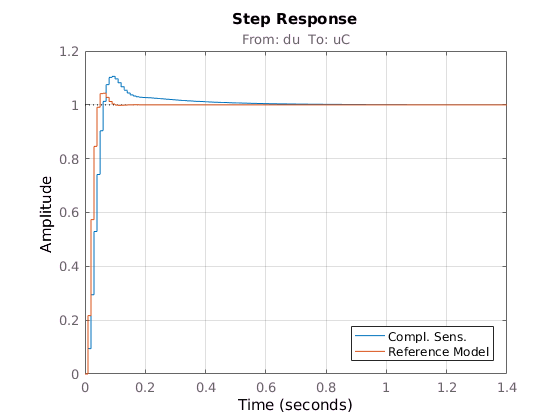

PitchRateModel = tf(.4323,  [1, 1.334]);
Ri = pid(.3, .3, .05, .01);
Mixer = 66.6667;
integrator = tf(1, [1, 0]);

InnerLoop = loopsens(PitchRateModel * Mixer, Ri); 

PlantModel = InnerLoop.Ti * integrator; 
OuterLoop = loopsens(c2d(PlantModel, Ts), HybridVRFTController); 

figure();
    step(OuterLoop.Ti, OuterReferenceModel_dt);
    legend('Compl. Sens.', 'Reference Model', 'Location', 'southEast');
    grid on;

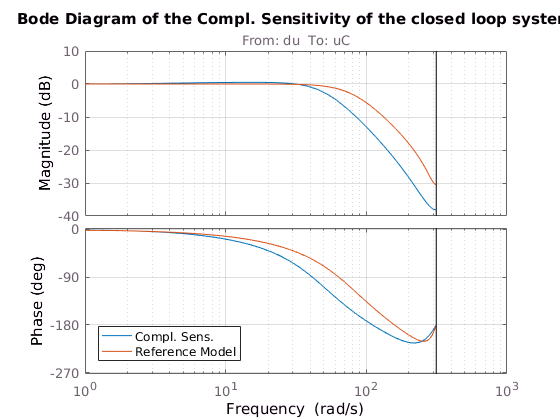

    
figure()
    bode(OuterLoop.Ti, OuterReferenceModel_dt);
    legend('Compl. Sens.', 'Reference Model', 'Location', 'southWest');
    title('Bode Diagram of the Compl. Sensitivity of the closed loop system');

    grid on; 